# QTRK Circular Deblurring Experiments using MRI Data

clear;clc;close all;
addpath("../../corruption")
addpath("../")
addpath("../tproduct toolbox 2.0 (transform)/")


%import data
load mri;                               %loads mri video as order-4 tensor
X = squeeze(double(D));                 %gets rid of dimension 1 mode
X = mat2gray(X(:,:,1:12));              %takes only first 12 frames   
[m,n,p] = size(X);                      %m1 = 128, n1 = 128, p = 12

%Using Gaussian Filter

h = fspecial('gaussian',[5,5],2);       %builds a Gaussian low-pass filter
[m1,n1] = size(h);   

%Building circularly blurred images

Y = zeros(m,n,p);
for i = 1:p
    Y(:,:,i) = blurryimage(X(:,:,i), h, [m,n]);
end

%% Creating a t-linear system corresponding to the deblurring problem

X_reorder = reorder_tensor(X,[m,n,p]);      %dimension n*p*m
Y_reorder = reorder_tensor(Y,[m,n,p]);

%Defining the t-linear measurement operator

A = circ_blurring_mxop(h, [m,n,p]);

% Add corruption to measurement tensor Y_reorder

num_its = 2000; % number of iterations
num_corrupt = 20; % number of corruption
q = 1-num_corrupt/(m*p*n); % quantile
k = 6; %number of corrupted rows

%corruptions are generated from normal distribution
mean_corrupt = 100;
deviation_corrupt = 20;

% Generate random corruption values f
corruption_values = mean_corrupt + deviation_corrupt*randn(num_corrupt, 1);

% Generate k random row indices to corrupt
corrupt_rows = randsample(m, k);

% Distribute num_corrupt corruptions uniformly across the k rows
    for i = 1:num_corrupt
        % Select a random row from the chosen rows
        row_idx = corrupt_rows(randsample(k, 1));
        
        % Randomly select indices for the other dimensions
        col_idx = randsample(p, 1);
        depth_idx = randsample(n, 1);
    
        % Apply the corruption value
        Y_reorder(row_idx, col_idx, depth_idx) = Y_reorder(row_idx, col_idx, depth_idx) + corruption_values(i);
    end


X0 = zeros(n,p,m);
Xblurry = Y_reorder;
%apply tensor regression technique

[Z,its] = QTRK_new(A,Y_reorder,X0,num_its, q); % Adjust q as needed
Z_qtrk = recover_img(Z,[m,n,p]);
[Z,its] = tRK(A,Y_reorder,Xblurry,1000);
Z_trk = recover_img(Z,[m,n,p]);

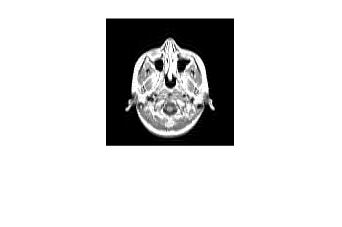

%close all
figure()
imshow(Z_trk(:,:,1),[0,1])

%imagesc(Y(:,:,1))

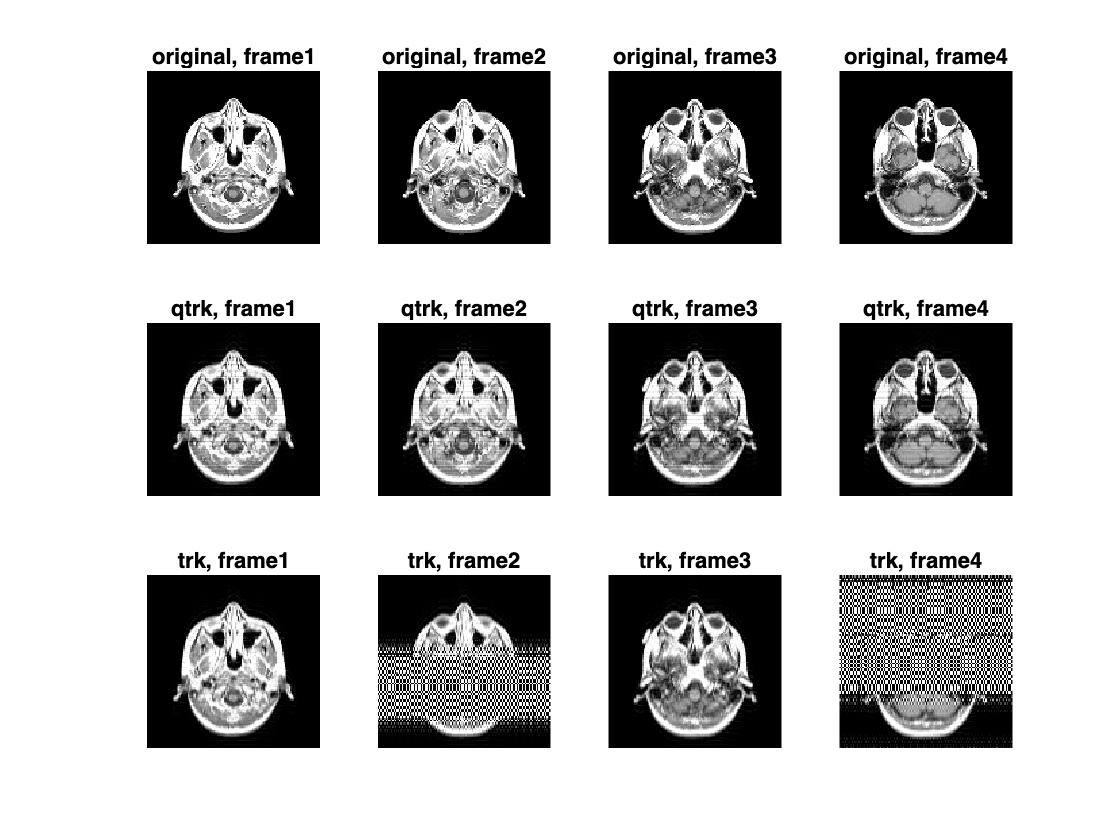

figure
it = 4;
for i = 1:it
    subplot(3,it,i)
    imshow(X(:,:,i),[0,1]);axis image off;
    title(sprintf('original, frame%d',i))

    subplot(3,it,i+it)
    imshow(Z_qtrk(:,:,i),[0,1]);axis image off;
    title(sprintf('qtrk, frame%d',i))
    
    subplot(3,it,i+2*it)
    imshow(Z_trk(:,:,i));axis image off;
    title(sprintf('trk, frame%d',i))    
end